clear;
close all;

% Load magnetometer data from CSV file
% data = readtable('./207smag_data_fixaxis2.csv'); % Update with the actual file path


% File paths for the input and cleaned output CSV files
input_csv_file = './209smag_data_fixaxis2.csv';
% cleaned_csv_file = 'cleaned_data.csv';

% Define thresholds for x, y, and z components
threshold_x = 5800;  % Example threshold for x
threshold_y = 5800;  % Adjust the threshold as needed
threshold_z = 5800;  % Adjust the threshold as needed

% Read the data from the CSV file into a table
data = readtable(input_csv_file);

% Display the first few rows to understand the structure
disp(data(1:5, :));

     Mag_X     Mag_Y      Mag_Z 
    _______    ______    _______

    -28.052    49.205    -66.372
    -28.052    49.205    -66.372
    -29.319    49.023    -67.598
    -29.319    49.023    -67.598
    -28.595    49.023    -66.897




% Filter the data to remove rows with x, y, or z values exceeding the thresholds
% data = data(data.Mag_X <= threshold_x | data.Mag_Y <= threshold_y | data.Mag_Z <= threshold_z, :);
data = data(data.Mag_X <= threshold_x, :)

data = 30000×3 table
     Mag_X     Mag_Y      Mag_Z 
    _______    ______    _______

    -28.052    49.205    -66.372
    -28.052    49.205    -66.372
    -29.319    49.023    -67.598
    -29.319    49.023    -67.598
    -28.595    49.023    -66.897
    -28.595    49.023    -66.897
    -29.138    49.568    -66.372
    -29.138    49.568    -66.372
    -29.138    49.205    -67.072
    -29.138    49.205    -67.072
    -28.414    50.294    -66.372
    -28.414    50.294    -66.372
    -27.871    49.386    -65.847
    -27.871    49.386    -65.847
    -26.966    48.115    -67.423
    -26.966    48.115    -67.423



% Save the cleaned data to a new CSV file
% writetable(cleaned_data, cleaned_csv_file);

% disp(['Data cleaned and saved to ', cleaned_csv_file]);

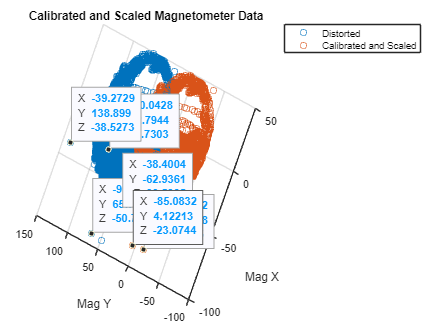




% Extract magnetometer columns
mag_ave = [data.Mag_X, data.Mag_Y, data.Mag_Z]; 

% Visualize the raw (distorted) magnetometer data
figure;
scatter3(mag_ave(:,1), mag_ave(:,2), mag_ave(:,3));
xlabel('Mag X'); ylabel('Mag Y'); zlabel('Mag Z');
title('Distorted Magnetometer Data (Before Calibration)');
grid on;
hold on;

% Find calibration coefficients using magcal
[A, b, expMFS] = magcal(mag_ave);

% Calculate scaling factors for each axis
x_scale = (max(mag_ave(:,1)) - min(mag_ave(:,1))) / 2;
y_scale = (max(mag_ave(:,2)) - min(mag_ave(:,2))) / 2;
z_scale = (max(mag_ave(:,3)) - min(mag_ave(:,3))) / 2;

% Combine scales into a vector
scale_factors = [x_scale, y_scale, z_scale];

% Apply the calibration and scaling to the raw data
xCorrected = (mag_ave - b) * A;

% Apply scaling factors to the corrected data
xCorrected_scaled = xCorrected ./ scale_factors;

% Visualize the calibrated and scaled magnetometer data
scatter3(xCorrected(:,1), xCorrected(:,2), xCorrected(:,3));
xlabel('Mag X'); ylabel('Mag Y'); zlabel('Mag Z');
title('Calibrated and Scaled Magnetometer Data');
legend('Distorted', 'Calibrated and Scaled');
grid on;


% Display calibration results
disp('Soft iron correction matrix (A):');

Soft iron correction matrix (A):


disp(A); % Soft iron correction matrix

    0.9404   -0.0026    0.0446
   -0.0026    1.0267    0.0145
    0.0446    0.0145    1.0380



disp('Hard iron correction bias (b):');

Hard iron correction bias (b):


disp(b); % Hard iron correction bias

   -2.1702   61.6808  -32.3492



disp('Scaling factors:');

Scaling factors:


disp(['X scale: ', num2str(x_scale)]);

X scale: 70.8541


disp(['Y scale: ', num2str(y_scale)]);

Y scale: 69.54


disp(['Z scale: ', num2str(z_scale)]);

Z scale: 62.782


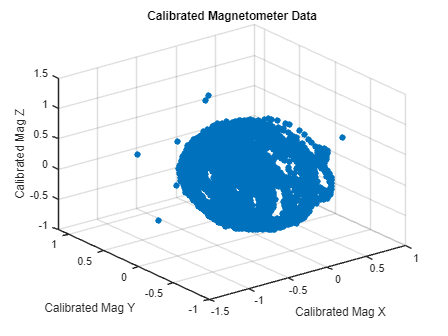


% Apply the calibration
calibratedMagData = (mag_ave - b) * A;

% Apply scaling factors to the corrected data
xCorrected_scaled = calibratedMagData ./ scale_factors;

% Visualize calibrated data
figure;
scatter3(xCorrected_scaled(:,1), xCorrected_scaled(:,2), xCorrected_scaled(:,3), 'filled');
xlabel('Calibrated Mag X'); ylabel('Calibrated Mag Y'); zlabel('Calibrated Mag Z');
title('Calibrated Magnetometer Data');
grid on;


% Save the calibrated data if needed
writetable(array2table(calibratedMagData, 'VariableNames', {'Mag_X', 'Mag_Y', 'Mag_Z'}), 'calibrated_magnetometer.csv');